Clustering Problem of two sets of dot clouds


% first ellipse
a1 = 3;
b1 = 1;
alpha1 = 0;
xc1 = -2;
yc1 = 1;
% second ellipse
a2 = 4;
b2 = 1;
alpha2 = pi/4;
xc2 = 2;
yc2 = -1;
% Get ellipces
[x1, y1] = getEllipse(a1, b1, alpha1, xc1, yc1);
[x2, y2] = getEllipse(a2, b2, alpha2, xc2, yc2);


Constructing hyperplane using  Linear Programming

% constraints
A = [-x1, -y1, ones(500, 1), -ones(500,1);
      x2,  y2, -ones(500,1), ones(500,1)];
b = zeros(1000,1) - 1;
% objective function
F = [0 0 0 1];
sol = linprog(F, A, b, [], [], [-inf, -inf, -inf, 0], [inf, inf, inf, inf]); 

Optimal solution found.



sol

sol =    -1.3378
    2.4611
         0
         0


Plotting

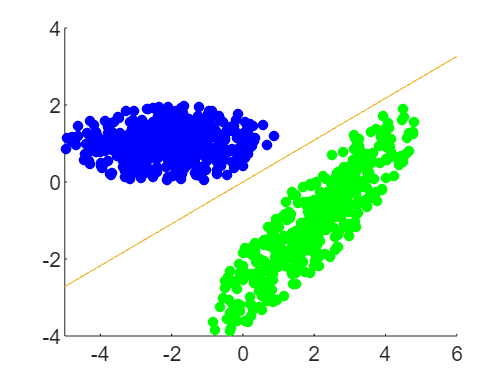

% Plot
figure
scatter(x1, y1, 20, 'blue', 'filled');
hold on
scatter(x2, y2, 20, 'green', 'filled');
hold on
xline = linspace(-5, 6, 250);
yline = - sol(1)/sol(2) .* xline  + sol(3)/sol(2);
plot(xline, yline);

Constructing hyperplane using SDP

% variables to find
% variables to find
a_ = sdpvar(2,1);
b_ = sdpvar(1);
t_ = sdpvar(1);
% objective function
F_ = t_;
%constraints
X_ = [x1'; y1'];
Y_ = [x2'; y2'];
LMI_ = [eye(2), a_;
        a_',    t_];
constr_ = [LMI_ >=0; a_'*X_ - b_ >= 0; a_'*Y_ - b_ <= 0];
optimize(constr_, F_);


 num. of constraints =  4
 dim. of sdp    var  =  3,   num. of sdp  blk  =  1
 dim. of linear var  = 1000
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|7.0e+04|9.7e+02|4.7e+06| 2.000000e+01  0.000000e+00| 0:0:00| chol  1  1 
 1|0.554|0.554|3.1e+04|4.3e+02|3.0e+06| 4.629357e+02 -2.573386e+02| 0:0:00| chol  1  1 
 2|0.402|0.402|1.9e+04|2.6e+02|2.3e+06| 1.294816e+03 -9.488035e+02| 0:0:00| chol  1  1 
 3|0.312|0.311|1.3e+04|1.8e+02|2.0e+06| 2.630881e+03 -2.176467e+03| 0:0:00| chol  1  1 
 4|0.257|0.255|9.6e+03|1.3e+02|1.8e+06| 4.542376e+03 -4.007498e+03| 0:0:00| chol  1  1 
 5|0.215|0.214|7.5e+03|1.0e+02|1.6e+06| 7.

a_opt_ = value(a_)

a_opt_ =  -352.7748
  315.2112


b_opt_ = value(b_)

b_opt_ = -115.1798

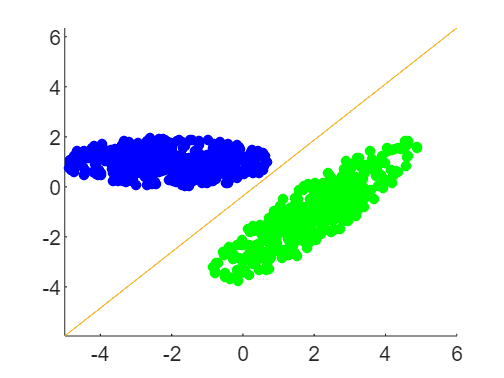

% Plot
% Plot
figure
scatter(x1, y1, 20, 'blue', 'filled');
hold on
scatter(x2, y2, 20, 'green', 'filled');
hold on
xline_ = linspace(-5, 6, 250);
yline_ = - a_opt_(1)/a_opt_(2) .* xline_  + b_opt_/a_opt_(2);
plot(xline_, yline_);

Divide intersected sets of dots linear prog with u and v as vectors

% generate points
A1 = 3;
B1 = 2.5;
A2 = 4;
B2 = 2;
[x11, y11] = getEllipse(A1, B1, alpha1, xc1, yc1);
[x22, y22] = getEllipse(A2, B2, alpha2, xc2, yc2);
% objective function
F1 = [0 0 0 ones(1,1000)];
% constraints
A1 = [-x1, -y1, ones(500, 1);
      x2,  y2, -ones(500,1)];
A2 = [A1 -ones(1000)];
sol1 = linprog(F1, A2, b, [], [], [-inf, -inf, -inf, zeros(1,1000)]); 

Optimal solution found.



sol1 = sol1(1:3) % a1 a2 b

sol1 =    -1.1084
    1.0099
   -0.7900


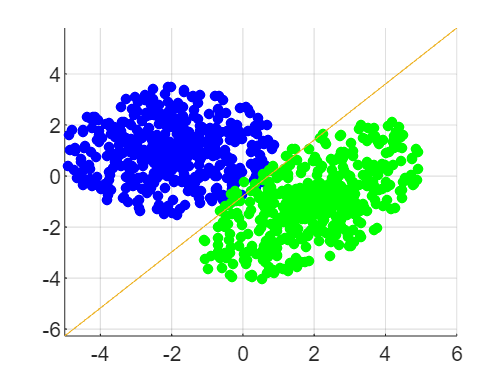

% Plot
figure
scatter(x11, y11, 20, 'blue', 'filled');
grid on
hold on
scatter(x22, y22, 20, 'green', 'filled');
hold on
xline1 = linspace(-5, 6, 250);
yline1 = - sol1(1)/sol1(2) .* xline  + sol1(3)/sol1(2);
plot(xline1, yline1);

% count quality metrics
blueDotsFalsePositive = sum((sol(1:2)'*[x11'; y11'] - sol(3)) < 0);
greenDotsFalsePositive = sum((sol(1:2)'*[x22'; y22'] - sol(3)) >= 0);
classifAccur = (blueDotsFalsePositive + greenDotsFalsePositive)/1000*100; 
classifAccur

classifAccur = 4.5000

Divide intersected sets of dots SDP and scalar u and v

% variables to find
a = sdpvar(1,2);
x0 = sdpvar(2,1);
u = sdpvar(1);
v = sdpvar(1);
% objective function
F = u + v;
%constraints
X = [x11'; y11'];
Y = [x22'; y22'];
constr = [a*X - a*x0 >= 1 - u; a*Y - a*x0 <= -1 + v; u >= 0; v >=0];
optimize(constr, F);

Your initial point x0 is not between bounds lb and ub; FMINCON
shifted x0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    1.980000e+00    1.000e-02    2.990e+00
    1       2    2.915296e+00    6.993e-02    2.990e+00    6.704e-01
    2       3    4.800023e+00    0.000e+00    2.973e+00    1.350e+00
    3       4    7.960981e+00    0.000e+00    2.943e+00    2.266e+00
    4       5    1.609474e+01    0.000e+00    2.867e+00    5.848e+00
    5       6    3.313983e+01    0.000e+00    2.714e+00    1.246e+01
    6       7    4.317700e+01    0.000e+00    2.628e+00    7.416e+00
    7       8    3.992331e+01    0.000e+00    2.671e+00    8.862e+00
    8      11    3.415029e+01    0.000e+00    2.731e+00    1.009e+01
    9      12    2.920688e+01    0.000e+00    2.789e+00    1.036e+01
   10      13    4.793957e+01    0.000e+00    2.786e+00    1.865e+01
   11    

a_opt = value(a)

a_opt = 1.0e-03 *

   -0.1403    0.1471


x0_opt = value(x0)

x0_opt =    19.9028
   18.4981


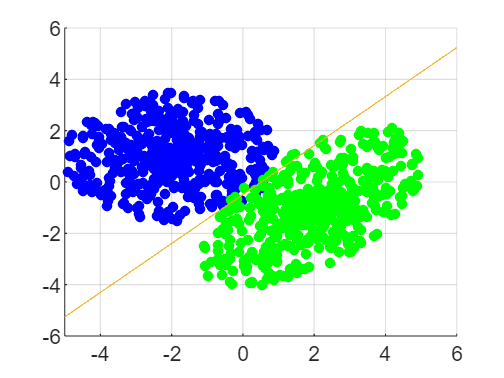

% Plot
figure
scatter(x11, y11, 20, 'blue', 'filled');
hold on
grid on
scatter(x22, y22, 20, 'green', 'filled');
hold on
xline2 = linspace(-5, 6, 250);
yline2 = - a_opt(1)*(xline2 - x0_opt(1))/a_opt(2) + x0_opt(2);
plot(xline2, yline2);

% count quality metrics
blueDotsFalsePositive2 = sum((a_opt*[x11'; y11'] - a_opt*x0_opt) < 0);
greenDotsFalsePositive2 = sum((a_opt*[x22'; y22'] - a_opt*x0_opt) >= 0);
classifAccur2 = (blueDotsFalsePositive2 + greenDotsFalsePositive2)/1000*100; 
classifAccur2

classifAccur2 = 1.6000

function [x, y] = getEllipse(a, b, alpha, xc, yc)
    % generate points
    %rng(1); % seed
    phi = 2 * pi .* rand(500,1);
    %rng(1);
    r = rand(500,1);
    % parametric ellipse equation
    x = xc + a.*r.*cos(phi)*cos(alpha) - b.*r.*sin(phi)*sin(alpha);
    y = yc + a.*r.*cos(phi)*sin(alpha) + b.*r.*sin(phi)*cos(alpha);
end